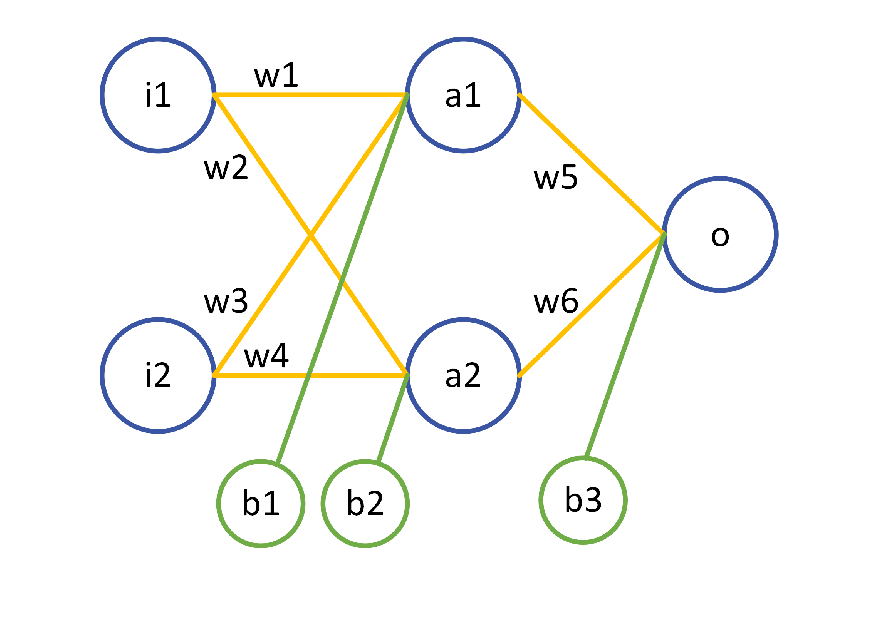

clear all

% XOR data
X = [0 0 1 1; 0 1 0 1];
y = [0 1 1 0];

% Set epochs and learning rate for Manual and MATLAB NN
epochs = 1000;
l_rate = 0.1;

% Set intial weights and biases
[w1, w2, w3, w4, w5, w6] = deal(0.01, -0.1, 0.5, 1, 0.04, 0.7);
[b1, b2, b3] = deal(0.01, 0.02, 0.03);

img = imread('NN_Architecture.png');
imshow(img, 'InitialMagnification',35)

## Train NN from Scratch

% Train the NN
[W1, W2, W3, W4, W5, W6, B1, B2, B3, manual_results_hist, manual_wb_hist] = fit(X, y, epochs, l_rate, w1, w2, w3, w4, w5, w6, b1, b2, b3);

% Make prediction
manual_results = zeros(1,4);
for k = 1:size(X, 2)
    [~, ~, ~, ~, o] = feed_forward(X(:, k), W1, W2, W3, W4, W5, W6, B1, B2, B3);
    manual_results(k) = o;
end
manual_results;
% store in same order as 'getwb' function for comparison
manual_wb = [W1, W2, W3, W4, W5, W6, B1, B2, B3];

manual_results_hist = array2table(manual_results_hist,...
    'VariableNames',{' 0 ' ' 1 ' '1' '0'},...,...
    'RowNames',{'Epoch 0';'Epoch 200';'Epoch 400';'Epoch 600';'Epoch 800';'Epoch 1000'}'); 
manual_results_hist = table(manual_results_hist, 'VariableNames',{'Manual - Results History'});
manual_wb_hist = array2table(manual_wb_hist,...
    'VariableNames',{'w1' 'w2' 'w3' 'w4' 'w5' 'w6' 'b1' 'b2' 'b3'},...,...
    'RowNames',{'Epoch 0';'Epoch 200';'Epoch 400';'Epoch 600';'Epoch 800';'Epoch 1000'}'); 
manual_wb_hist = table(manual_wb_hist, 'VariableNames',{'Manual - Weights and Biases History'});

## Train NN using Deep Learning Toolbox

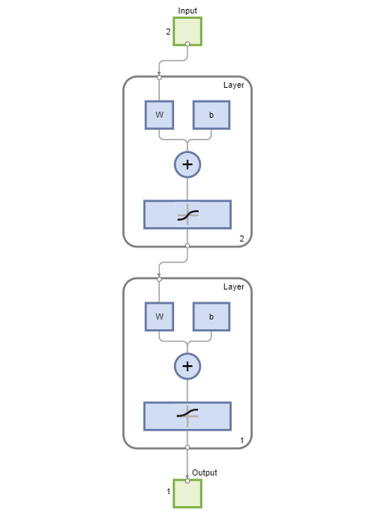

% Create NN (this ensures no default preprocessing is applied)
% 1 input layer
% 1 hidden layer (2 nodes, tanh activation Fcn)
% 1 output layer (sigmoid activation Fcn)
net = network;
net.numInputs = 1;
net.numLayers = 2;
net.layers{1}.size = 2;
net.layers{1}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'logsig';
net.inputConnect(1) = 1;
net.biasConnect(1) = 1;
net.biasConnect(2) = 1;
net.layerConnect = [0 0; 1 0];
net.outputConnect = [0 1];

% Use batch gradient descent algorithm
net.trainFcn = 'traingd';

% Set loss as Mean Squared Error
net.performFcn = 'mse';

% Set epoch to 1
% training function "traingd" uses the batch gradient descent algorithm
% and uses the entire dataset for each epoch
% Hence, the epoch is set to one, and the weights are updated
% for every sample in the dataset individually.
net.trainParam.epochs = 1;

% Set learning rate
net.trainParam.lr = l_rate;

% Use all data to train
net.divideMode = 'none';
net.trainParam.showWindow = 0;

%% Configure the network
net = configure(net, X, y);

% Set weights and bias
net.IW{1} = [w1 w3; w2 w4];
net.LW{2} = [w5 w6];
net.b = {[b1; b2]; b3};D
view(net)


i = 1;
% make prediction
MATLAB_results_hist(i, 1:4) = sim(net,X);
MATLAB_wb_hist(i,1:9) = getwb(net);
i = i + 1;

% train for specified number of epoch
for e = 1:epochs
    % train for each sample in X
    for k = 1:size(X, 2)
        [net] = train(net, X(:, k), y(k));
    end
    % store results each 200 epoch
    if(mod(e,200) == 0)
        % make prediction
        MATLAB_results_hist(i, 1:4) = sim(net,X);
        MATLAB_wb_hist(i,1:9) = getwb(net);
        i = i + 1;
    end
end

% Make prediction and store results
MATLAB_results = sim(net,X);
MATLAB_wb = getwb(net)';
MATLAB_wb = MATLAB_wb(:,[3 4 5 6 8 9 1 2 7]);

MATLAB_results_hist = array2table(MATLAB_results_hist,...
    'VariableNames',{' 0 ' ' 1 ' '1' '0'},...,...
    'RowNames',{'Epoch 0';'Epoch 200';'Epoch 400';'Epoch 600';'Epoch 800';'Epoch 1000'}'); 
MATLAB_results_hist = table(MATLAB_results_hist, 'VariableNames',{'MATLAB - Results History'});

MATLAB_wb_hist = MATLAB_wb_hist(:,[3 4 5 6 8 9 1 2 7]);
MATLAB_wb_hist = array2table(MATLAB_wb_hist,...
    'VariableNames',{'w1' 'w2' 'w3' 'w4' 'w5' 'w6' 'b1' 'b2' 'b3'},...,...
    'RowNames',{'Epoch 0';'Epoch 200';'Epoch 400';'Epoch 600';'Epoch 800';'Epoch 1000'}'); 
MATLAB_wb_hist = table(MATLAB_wb_hist, 'VariableNames',{'MATLAB - Weights and Biases History'});

## Compare Results

### Final Results and Weights

compare_results = [manual_results; MATLAB_results];
compare_results = array2table(compare_results,...
    'VariableNames',{' 0 ' ' 1 ' '1' '0'},...,...
    'RowNames',{'Manual';'MATLAB'}); 
compare_results = table(compare_results, 'VariableNames',{'Compare Final Results'})

compare_results = 2×1 table
                   Compare Final Results                
                 0           1          1          0    
    ____________________________________________________

    Manual    0.077664    0.93828    0.93737    0.086069
    MATLAB    0.077664    0.93828    0.93737    0.086069


compare_wb = [manual_wb; MATLAB_wb];
compare_wb = array2table(compare_wb,...
    'VariableNames',{'w1' 'w2' 'w3' 'w4' 'w5' 'w6' 'b1' 'b2' 'b3'},...,...
    'RowNames',{'Manual';'MATLAB'}); 
compare_wb = table(compare_wb, 'VariableNames',{'Compare Final Weights and Biases'})

compare_wb = 2×1 table
    Compare Final Weights and Biases
    ________________________________

               1×9 table            
               1×9 table            


### Results History

manual_results_hist

manual_results_hist = 6×1 table
                    Manual - Results History                
                     0           1          1          0    
    ________________________________________________________

    Epoch 0         0.5111    0.64284    0.49373     0.63581
    Epoch 200      0.28503    0.57144    0.62474     0.60707
    Epoch 400       0.1961    0.62876    0.74484     0.49588
    Epoch 600      0.14732    0.87372    0.86986     0.17767
    Epoch 800     0.098875    0.91995    0.91843     0.11191
    Epoch 1000    0.077664    0.93828    0.93737    0.086069


MATLAB_results_hist

MATLAB_results_hist = 6×1 table
                    MATLAB - Results History                
                     0           1          1          0    
    ________________________________________________________

    Epoch 0         0.5111    0.64284    0.49373     0.63581
    Epoch 200      0.28503    0.57144    0.62474     0.60707
    Epoch 400       0.1961    0.62876    0.74484     0.49588
    Epoch 600      0.14732    0.87372    0.86986     0.17767
    Epoch 800     0.098875    0.91995    0.91843     0.11191
    Epoch 1000    0.077664    0.93828    0.93737    0.086069


### Weights History

manual_wb_hist

manual_wb_hist = 6×1 table
    Manual - Weights and Biases History
    ___________________________________

                 1×9 table             
                 1×9 table             
                 1×9 table             
                 1×9 table             
                 1×9 table             
                 1×9 table             


MATLAB_wb_hist

MATLAB_wb_hist = 6×1 table
    MATLAB - Weights and Biases History
    ___________________________________

                 1×9 table             
                 1×9 table             
                 1×9 table             
                 1×9 table             
                 1×9 table             
                 1×9 table             


## Functions for Manual NN

function [i1, i2, a1, a2, o] = feed_forward(x_sample, w1, w2, w3, w4, w5, w6, b1, b2, b3)
    i1 = x_sample(1);
    i2 = x_sample(2);
    % Multiply inputs by the weights and apply the activation function
    z1 = i1 * w1 + i2 * w3 + b1;
    a1 = tanh(z1);
    z2 = i1 * w2 + i2 * w4 + b2;
    a2 = tanh(z2);
    zo = a1 * w5 + a2 * w6 + b3;
    o = sigmoid(zo);
end

function [dL_dw1, dL_dw2, dL_dw3, dL_dw4, dL_dw5, dL_dw6, dL_db1, dL_db2, dL_db3] = back_prop(w5, w6, i1, i2, a1, a2, o, y)
    % Set loss as Mean Squared Error
    dL_do = 2 * (o - y);

     % Calculate the gradients for weights and bias in the output layer
    do_zo = d_sigmoid(o);
    [dzo_dw5, dzo_dw6, dzo_db3] = deal(a1, a2, 1);
    dL_dw5 = dL_do * do_zo * dzo_dw5;
    dL_dw6 = dL_do * do_zo * dzo_dw6;
    dL_db3 = dL_do * do_zo * dzo_db3;

    % Calculate the gradients for weights and bias in the hidden layer
    dzo_da2 = w6;
    da2_dz2 = d_tanh(a2);
    [dz2_dw2, dz2_dw4, dz2_db2] = deal(i1, i2, 1);
    dL_dw2 = dL_do * do_zo * dzo_da2 * da2_dz2 * dz2_dw2;
    dL_dw4 = dL_do * do_zo * dzo_da2 * da2_dz2 * dz2_dw4;
    dL_db2 = dL_do * do_zo * dzo_da2 * da2_dz2 * dz2_db2;

    dzo_da1 = w5;
    da1_dz1 = d_tanh(a1);
    [dz1_dw1, dz1_dw3, dz1_db1] = deal(i1, i2, 1);
    dL_dw1 = dL_do * do_zo * dzo_da1 * da1_dz1 * dz1_dw1;
    dL_dw3 = dL_do * do_zo * dzo_da1 * da1_dz1 * dz1_dw3;
    dL_db1 = dL_do * do_zo * dzo_da1 * da1_dz1 * dz1_db1;
end

function [w1, w2, w3, w4, w5, w6, b1, b2, b3] = fit_sample(sample_x, sample_y, learning_rate, w1, w2, w3, w4, w5, w6, b1, b2, b3)
    % feed forward
    [i1, i2, a1, a2, o] = feed_forward(sample_x, w1, w2, w3, w4, w5, w6, b1, b2, b3);

    % back propagate
    [dL_dw1, dL_dw2, dL_dw3, dL_dw4, dL_dw5, dL_dw6, dL_db1, dL_db2, dL_db3] = back_prop(w5, w6, i1, i2, a1, a2, o, sample_y);
    
    % gradient descent - update all weights and biases
    w1 = w1 - learning_rate*dL_dw1;
    w2 = w2 - learning_rate*dL_dw2;
    w3 = w3 - learning_rate*dL_dw3;
    w4 = w4 - learning_rate*dL_dw4;
    w5 = w5 - learning_rate*dL_dw5;
    w6 = w6 - learning_rate*dL_dw6;
    b1 = b1 - learning_rate*dL_db1;
    b2 = b2 - learning_rate*dL_db2;
    b3 = b3 - learning_rate*dL_db3;
end

function [w1, w2, w3, w4, w5, w6, b1, b2, b3, result, wb] = fit(X, y, epochs, l_rate, w1, w2, w3, w4, w5, w6, b1, b2, b3)
    i = 1;
    % make prediction
    for k = 1:size(X, 2)
        [~, ~, ~, ~, o] = feed_forward(X(:, k), w1, w2, w3, w4, w5, w6, b1, b2, b3);
        result(i, k) = o;
    end
    wb(i,1:9) = [w1, w2, w3, w4, w5, w6, b1, b2, b3];
    i = i + 1;

    % train for specified number of epoch
    for e = 1:epochs
        % train for each sample in X
        for k = 1:size(X, 2)
            [w1, w2, w3, w4, w5, w6, b1, b2, b3] = fit_sample(X(:, k), y(k), l_rate, w1, w2, w3, w4, w5, w6, b1, b2, b3);
        end

        % store results each 200 epoch
        if(mod(e,200) == 0)
            % make prediction
            for k = 1:size(X, 2)
                [~, ~, ~, ~, o] = feed_forward(X(:, k), w1, w2, w3, w4, w5, w6, b1, b2, b3);
                result(i, k) = o;
            end
            wb(i,1:9) = [w1, w2, w3, w4, w5, w6, b1, b2, b3];
            i = i + 1;
        end
    end
end

function g = sigmoid(z)
    g = 1 / (1 + exp(-z));
end

function g = d_sigmoid(z)
    g = z*(1 - z);  % derivative of sigmoid activation function
end

function g = d_tanh(z)
    g = 1 - z^2;    % derivative of tanh activation function
end